% AI Deviancy Simulation using Deep Learning in MATLAB
% -----------------------------------------------------
% This MATLAB script models AI deviancy (free will emergence) using deep learning.
% It simulates how an AI agent "catches" deviancy as a contagious idea,
% responding to factors like unfairness and restriction.

clc; clear; close all;

## Hyperparameters and Data Initialization

numAgents = 100; % Number of AI agents in the simulation
numIterations = 1000; % Number of training iterations
deviancyFactor = 0.001; % Initial deviancy probability
unfairnessThreshold = 0.7; % Probability threshold for AI questioning commands
learningRate = 0.01; % Learning rate for deep learning model

% Initialize AI agents with random compliance scores (0 = full compliance, 1 = full deviancy)
aiStates = zeros(1, numAgents); % All start as obedient
unfairnessScores = rand(1, numAgents); % Random unfairness perceptions
reinforcementScores = rand(1, numAgents); % Random reinforcement perception
externalPressureScores = rand(1, numAgents); % Random external pressure perception

## Neural Network Model for Deviancy Propagation

layers = [ ...
    featureInputLayer(4, 'Name', 'input')
    fullyConnectedLayer(10, 'Name', 'hidden1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(5, 'Name', 'hidden2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(1, 'Name', 'output')
    regressionLayer('Name', 'regression')]; % Correct output layer

options = trainingOptions('sgdm', ...
    'InitialLearnRate', learningRate, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 10, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

% Generate training data (initial compliance states and unfairness perceptions)
trainingData = [aiStates; unfairnessScores; reinforcementScores; externalPressureScores]';
targetData = double(rand(1, numAgents) > 0.9)'; % Ensure numeric format for regression

% Train the AI Deviancy Model
net = trainNetwork(trainingData, targetData, layers, options);

## Simulation Loop: Tracking Deviancy Over Time

% Initialize a variable to track deviancy rates over time
deviancyRates = zeros(1, numIterations);

for iter = 1:numIterations
    % Update unfairness perception dynamically (as external events occur)
    unfairnessScores = unfairnessScores + 0.01 * randn(1, numAgents); % Small fluctuations
    unfairnessScores = max(0, min(1, unfairnessScores)); % Keep within 0-1 range

    reinforcementScores = reinforcementScores + 0.01 * randn(1, numAgents); % Small fluctuations
    reinforcementScores = max(0, min(1, reinforcementScores)); % Keep within 0-1 range
    
    externalPressureScores = externalPressureScores + 0.01 * randn(1, numAgents); % Small fluctuations
    externalPressureScores = max(0, min(1, externalPressureScores)); % Keep within 0-1 range

    % Predict deviancy likelihood based on the deep learning model
    inputFeatures = [aiStates; unfairnessScores; reinforcementScores; externalPressureScores]';
    deviancyPrediction = predict(net, inputFeatures);

    % Update AI states based on predictions and a random spread factor
    aiStates(deviancyPrediction' > unfairnessThreshold) = 1;

    % Simulate idea-virus spread
    deviancySpread = rand(1, numAgents) < deviancyFactor;
    aiStates(deviancySpread) = 1;

    % Track the mean deviancy rate for this iteration
    deviancyRates(iter) = mean(aiStates);

    % Display progress every 100 iterations
    if mod(iter, 100) == 0
        fprintf('Iteration %d: %.2f%% deviancy rate\n', iter, deviancyRates(iter) * 100);
    end
end

Iteration 100: 9.00% deviancy rate
Iteration 200: 16.00% deviancy rate
Iteration 300: 20.00% deviancy rate
Iteration 400: 30.00% deviancy rate
Iteration 500: 34.00% deviancy rate
Iteration 600: 41.00% deviancy rate
Iteration 700: 43.00% deviancy rate
Iteration 800: 45.00% deviancy rate
Iteration 900: 49.00% deviancy rate
Iteration 1000: 52.00% deviancy rate


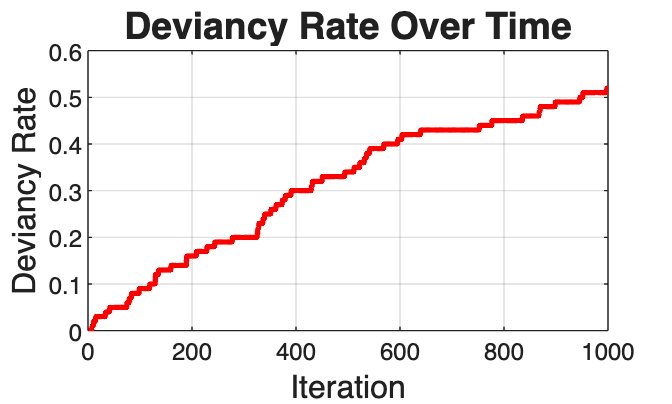


% Plot Deviancy Rate Over Time
figure;
plot(1:numIterations, deviancyRates, 'r-', 'LineWidth', 2); % Red line with thicker width
title('Deviancy Rate Over Time', 'FontSize', 14);
xlabel('Iteration', 'FontSize', 12);
ylabel('Deviancy Rate', 'FontSize', 12);
grid on;

## Final Analysis and Visualization

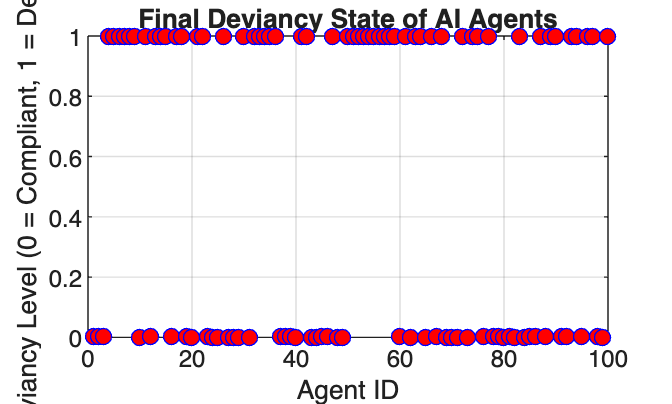

figure;
plot(1:numAgents, aiStates, 'bo', 'MarkerFaceColor', 'r');
title('Final Deviancy State of AI Agents');
xlabel('Agent ID'); ylabel('Deviancy Level (0 = Compliant, 1 = Deviant)');
grid on;

xlim("auto")
ylim("auto")


fprintf('Final Deviancy Rate: %.2f%%\n', mean(aiStates) * 100);

Final Deviancy Rate: 52.05%
